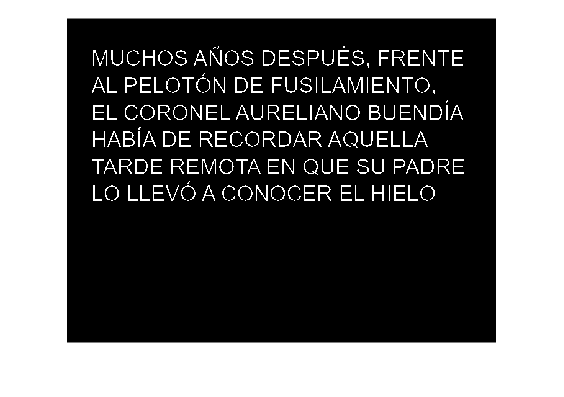

%%1. Binarization
task1Binarization('origen.png', 0.01);

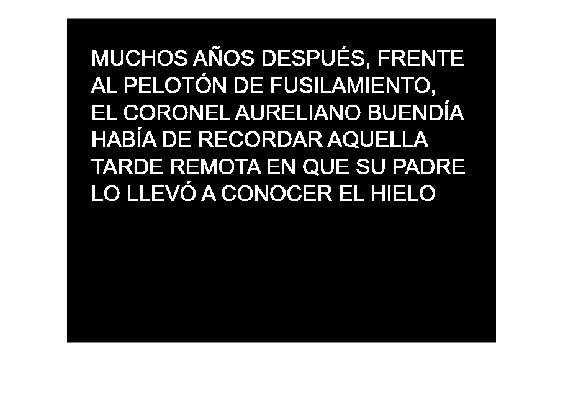

task1Binarization('origen.png', 0.99);

Lower threshold = líneas más finas, capta menos. A mayor theshold, mayor densidad de píxeles que ha captado. Otsu finds the optimal  threshold.

imBinarized = task1BinarizationAdvanced('origen.png');

Otsu threshold: 0.506


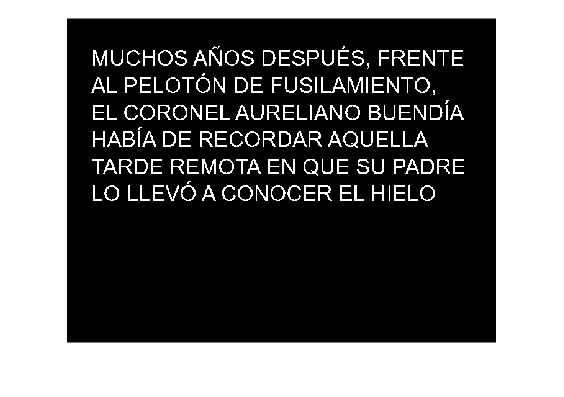

imshow(imBinarized); %solo para testeo, LUEGO QUITAR

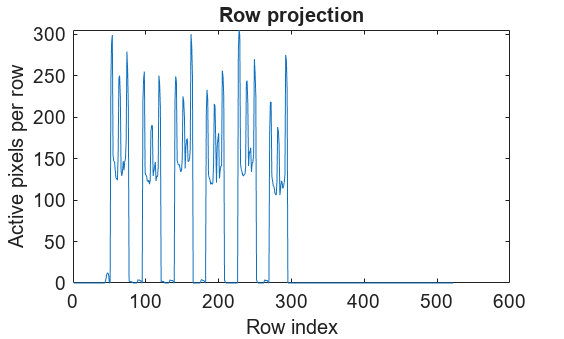

%%2. Segmenting Rows
% Method: vertical projection
% Sum image rows to detect text lines
rowProjection = task2RowProjection(imBinarized); 

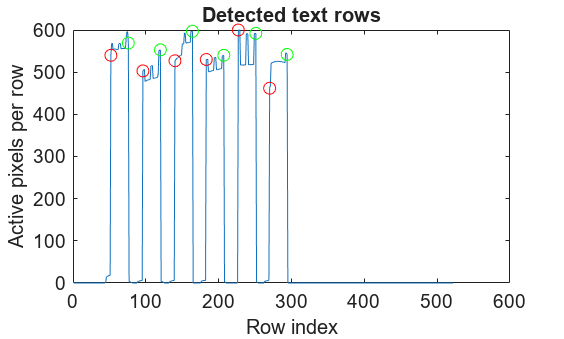


[rowStarts, rowEnds, rowMask] = task2SegmentRows(imBinarized);

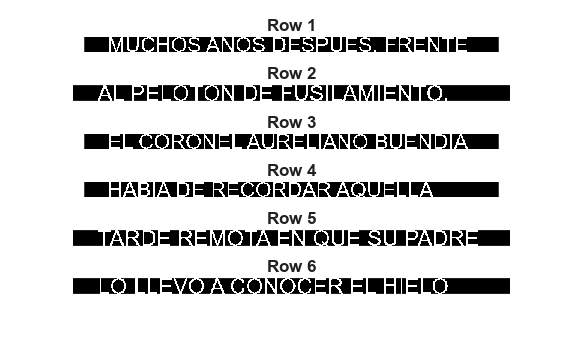

%Gives a cell 
rowImages = task2ExtractRows(imBinarized, rowStarts, rowEnds);

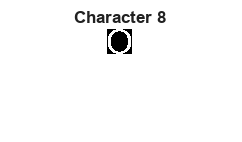

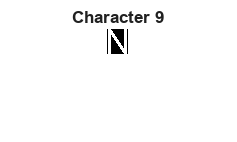

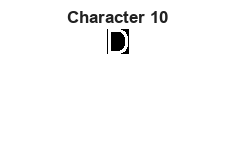

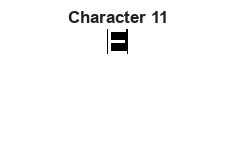

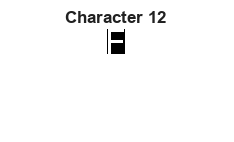

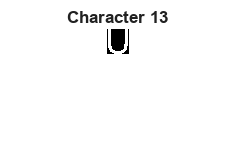

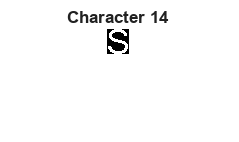

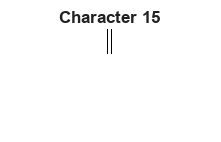

%TASK 3: Segmenting Characters. With vertical projection
%We are going to segment each row individually
numRows = length(rowImages); %Get the total number of rows
allChars = cell(1, numRows);
for i = 1:numRows
    allChars{i} = task3SegmentCharacters(rowImages{i});
end

## 4. Preproccessing

imResize = task4PreprocessingCharacters(allChars,32);

## 6. Recognition


img = imread('A.png');
[letter, score] = task6_recognize(img, 'alphabet/');